clear
%obtain the template of the sample ROI for template matching
sampX = 240;
sampY = 210;
[unused, template, templateMatcher] = constructTemplateMatcher(sampX, sampY)
%use the template to locate the initial position
[image, experimentalX, experimentalY] = locateSample(template, templateMatcher);
imshow(image);
hold on
plot(sampX, sampY, 'g.');
plot(experimentalX, experimentalY, 'r.');
hold off

%after drift
[image, x, y] = locateSample(template, templateMatcher);
imshow(image);
hold on
plot(x, y, 'r.');
hold off;

clear
sampX = 111;
sampY = 142;
template = constructTemplate(sampX, sampY);

Dot NET assembly loaded.
1 camera was discovered.
Opening the first camera
Starting software triggered image acquisition.
Image frame number: 1
Stopping software triggered image acquisition.
Releasing the camera
Dot NET assembly loaded.
1 camera was discovered.
Opening the first camera
Starting software triggered image acquisition.
Image frame number: 1
Stopping software triggered image acquisition.
Releasing the camera


[x,y, croppedImage] = actuallyWorkingTemplateMatching(template);

Dot NET assembly loaded.
1 camera was discovered.
Opening the first camera
Starting software triggered image acquisition.
Image frame number: 1
Stopping software triggered image acquisition.
Releasing the camera
Dot NET assembly loaded.
1 camera was discovered.
Opening the first camera
Starting software triggered image acquisition.
Image frame number: 1
Stopping software triggered image acquisition.
Releasing the camera


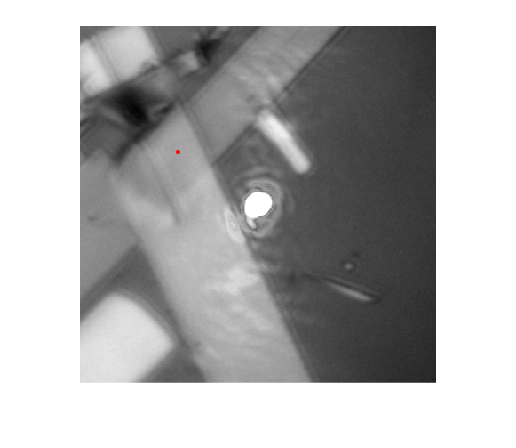

imshow(croppedImage);
hold on
plot(x,y, 'r.');
hold off

%after drift
[x,y, croppedImage] = actuallyWorkingTemplateMatching(template);

Dot NET assembly loaded.
1 camera was discovered.
Opening the first camera
Starting software triggered image acquisition.
Image frame number: 1
Stopping software triggered image acquisition.
Releasing the camera
Dot NET assembly loaded.
1 camera was discovered.
Opening the first camera
Starting software triggered image acquisition.
Image frame number: 1
Stopping software triggered image acquisition.
Releasing the camera


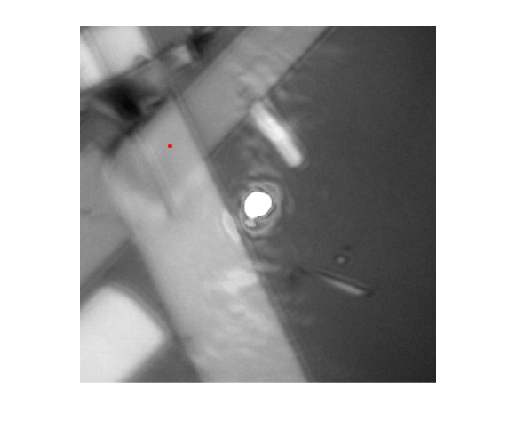

imshow(croppedImage);
hold on
plot(x, y, 'r.');
hold off;


%calculate offset distance
offsetX = 200 - x;
offsetY = 200 - y;

constant = 3.45/50;



%convert to input voltage
